# 线性调频脉冲雷达仿真

## 1 仿真目的

在MATLAB上实现线性调频信号（LMCW）的脉冲压缩（PC）、动目标显示（MTI）和动目标检测(MTD)、解速度度模糊以及恒虚警率检测（CFAR）等信号处理算法。 

## 2 仿真内容

采用线性调频的脉冲信号作为发射波形，通过设定雷达的工作参数、波形参数以及目标特性，在 MATLAB 中模拟雷达的目标回波信号。具体参数设定如下

### 2.1 参数设置

**1）雷达工作参数**

射频(脉冲发射的载频)：1.57GHz

中频信号采样频率：2MHz

中频信号信噪比：-12dB

**2）雷达波形参数**

发射信号带宽：2MHz

发射信号时宽：42us

发射脉冲重复周期：240us

模拟的目标回波脉冲数：16 个脉冲

%% 雷达参数设置
% ===================================================================================%
C=3.0e8;          %光速 (m/s)
RF=3.140e9/2;     %雷达射频
Lambda=C/RF;      %雷达工作波长
PulseNumber=16;   %回波脉冲数
BandWidth=2.0e6;  %发射信号带宽2G  
TimeWidth=42.0e-6;%发射信号时宽42us
PRT=240e-6;       %雷达发射脉冲重复周期(s)=240us，对应1/2*240*300=36000米
PRF=1/PRT;
Fs=2.0e6;            %采样频率2M
NoisePower=-12;%(dB);%噪声功率（目标为0dB）
% ---------------------------------------------------------------%
SampleNumber=fix(Fs*PRT);            %计算一个脉冲周期的采样点数480；
TotalNumber=SampleNumber*PulseNumber;%总的采样点数480*16=TotalNumber；
BlindNumber=fix(Fs*TimeWidth);       %计算一个脉冲周期的盲区-遮挡样点数=84；

**3）目标特性参数**

程序中根据学号的末尾三位来决定目标的仿真参数。学号的后三位为920，即X=9,Y=2,Z=0,相应的目标参数如下：

目标反射功率：[1，1,0.25,1]。

目标距离：[2800，8025，8025，9000+(Y*10+Z)*200]=[2800，8025，8025，13000],单位：米（m）。

目标径向速度：[50，-100，0，(200+X*10+Y*10+Z)]=[50，-100，0，310],单位：m/s。分别对应低速、负高速、静止和高速目标。

%% 目标参数设置                                       
%===================================================================================%
X=9;Y=2;Z=0;                                                           %这三个参数可控制目标的距离和速度

TargetNumber=4;                                                        %目标个数

SigPower(1:TargetNumber)=[1 1 0.25 1];                                 %目标功率,无量纲

TargetDistance(1:TargetNumber)=[2800 8025 8025 9000+(Y*10+Z)*200];     %目标距离,单位m 9200需要改9000+(Y*10+Z)*200

DelayNumber(1:TargetNumber)=fix(Fs*2*TargetDistance(1:TargetNumber)/C);% 把目标距离换算成采样点（距离门）

TargetVelocity(1:TargetNumber)=[50 -100 0 (200+X*10+Y*10+Z)];          %目标径向速度 单位m/s   230需要改为(200+X*10+Y*10+Z)

TargetFd(1:TargetNumber)=2*TargetVelocity(1:TargetNumber)/Lambda;      %计算目标多普勒

### 2.2 MATLAB 仿真

2.2.1 脉冲压缩

在 MATLAB 中对回波信号分别进行频域脉压和时域脉压。

2.2.2 动目标显示 (MTI)

相邻两脉冲做 MTI，即一次对消，产生15 个脉冲。

2.2.3 动目标检测 (MTD)

16 个脉冲到齐后，做MTD，输出16 个多普勒通道。

2.2.4 恒虚警率检测 (CFAR)

采用平均单元选大法(GO-CFAR)进行处理，对16 个参考单元取平均，左右各1 个保护单元。

## 3 过程

### 3.1 线性调频信号(Chirp Signal)

线性调频矩形脉冲信号的表达式为


$$s(t)=\frac{1}{\sqrt{T}}rect(\frac{t}{T})e^{j(2\pi f_0t+\mu t^2)}$$


其中，$\textrm{rect}\left(\frac{t}{T}\right)=\left\lbrace \begin{array}{ll}
1 & |t|\le \frac{T}{2}\\
0 & |t|>\frac{T}{2}
\end{array}\right.$，$T$为脉冲宽度，$\mu =\frac{B}{T}$为调制斜率，$B$为调频带宽。

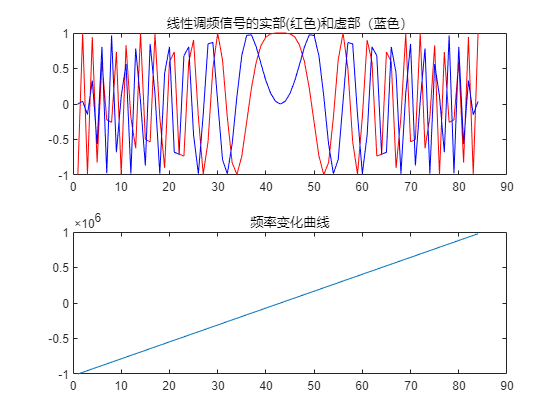

%% 产生线性调频信号                                  
%====================================================================================%
number=fix(Fs*TimeWidth);%回波的采样点数=脉压系数长度=暂态点数目+1=83+1
if rem(number,2)~=0
    number=number+1;
end                                                                                                                                                                   

for i=-fix(number/2):fix(number/2)-1
    Chirp(i+fix(number/2)+1)= exp(1j*(pi*(BandWidth/TimeWidth)*(i/Fs)^2));%exp(j*pi*ut^2)，u为调制斜率
    freq(i+fix(number/2)+1) = (BandWidth/TimeWidth)*(i/Fs);%f=ut
end   
coeff=conj(fliplr(Chirp));%产生脉压系数，对称反转，复共轭，h(t)=s*(-t)

%% 线性调频信号图示
figure(1);
subplot(2,1,1);
plot(real(Chirp),'r-');title('线性调频信号的实部(红色)和虚部（蓝色）');
hold on;
plot(imag(Chirp),'b-');
hold off;
subplot(2,1,2);plot(freq);title('频率变化曲线');

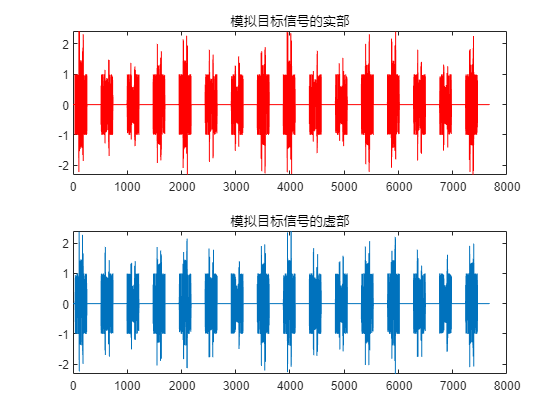

%% 产生目标回波串 
SignalAll=zeros(1,TotalNumber);%所有脉冲的信号,先填0
for k=1:TargetNumber% 依次产生各个目标1 2 3 4
    SignalTemp=zeros(1,SampleNumber);% 一个脉冲
    SignalTemp(DelayNumber(k):DelayNumber(k)+number-1)=sqrt(SigPower(k))*Chirp;%一个脉冲的1个目标（未加多普勒速度）
    Signal=zeros(1,TotalNumber);
    for i=1:PulseNumber
        Signal((i-1)*SampleNumber+1:i*SampleNumber)=SignalTemp;
    end
    FreqMove=exp(1j*2*pi*TargetFd(k)*(0:TotalNumber-1)/Fs);%目标的多普勒速度*时间=目标的多普勒相移
    Signal=Signal.*FreqMove;
    SignalAll=SignalAll+Signal;
end
%回波信号图示  7680点（未考虑盲区）
figure(2);
subplot(2,1,1);plot(real(SignalAll),'r-');title('模拟目标信号的实部');
subplot(2,1,2);plot(imag(SignalAll));title('模拟目标信号的虚部');

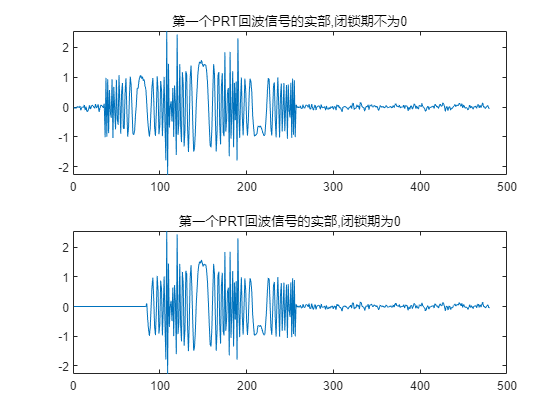

%% 产生系统噪声信号                               
%====================================================================================%
SystemNoise=normrnd(0,10^(NoisePower/10),1,TotalNumber)+1j*normrnd(0,10^(NoisePower/10),1,TotalNumber);
%====================================================================================%

%% 总的回波信号                                    
%====================================================================================%
Echo=SignalAll+SystemNoise;% +SeaClutter+TerraClutter;
figure;
subplot(2,1,1);plot(real(Echo(1:SampleNumber)));title('第一个PRT回波信号的实部,闭锁期不为0');hold on;
for i=1:PulseNumber   %在接收机闭锁期,接收的回波为0
    Echo((i-1)*SampleNumber+1:(i-1)*SampleNumber+number)=0;
end
subplot(2,1,2);plot(real(Echo(1:SampleNumber)));title('第一个PRT回波信号的实部,闭锁期为0');hold off;

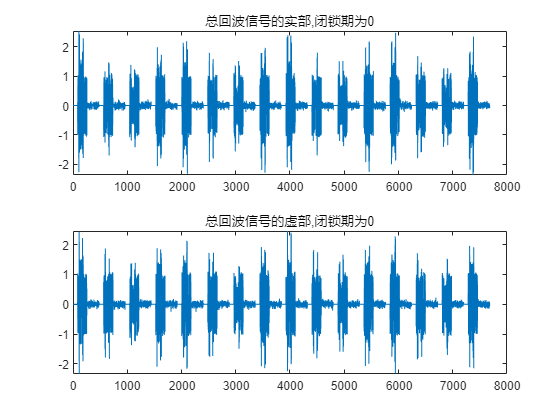

%%回波信号图示  7680点（有盲区）
figure;
subplot(2,1,1);plot(real(Echo));title('总回波信号的实部,闭锁期为0');
subplot(2,1,2);plot(imag(Echo));title('总回波信号的虚部,闭锁期为0');

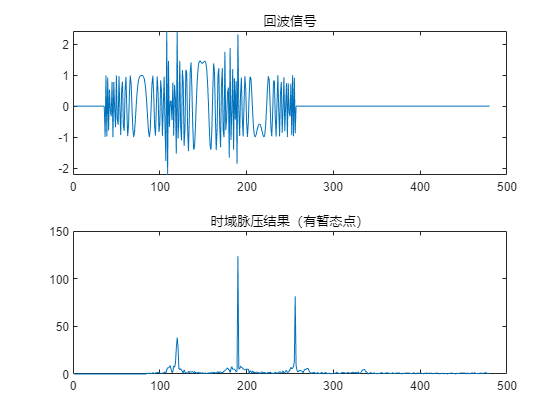

%% ================================时域脉压=================================%%
pc_time0 = conv(Echo,coeff);
pc_time1 = pc_time0(number:TotalNumber+number-1);%去掉暂态点 number-1个
% pc_time2 = pc_time0(number/2:TotalNumber+number/2-1);
% pc_time3 = pc_time0(1:TotalNumber-1);
figure();
subplot(2,1,1);plot(real(SignalAll(1:SampleNumber)));title('回波信号');
subplot(2,1,2);plot(abs(pc_time0(1:SampleNumber)));title('时域脉压结果（有暂态点）');

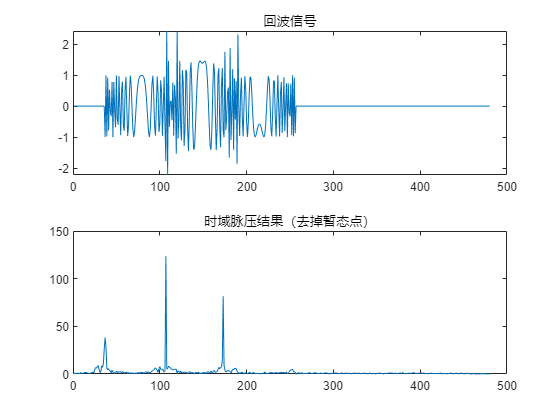


figure();
subplot(2,1,1);plot(real(SignalAll(1:SampleNumber)));title('回波信号');
subplot(2,1,2);plot(abs(pc_time1(1:SampleNumber)));title('时域脉压结果（去掉暂态点）');

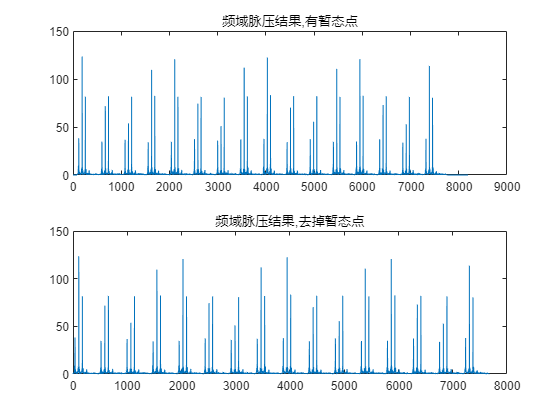

%% ================================频域脉压=================================%%
Echo_fft=fft(Echo,8192);%理应进行TotalNumber+number-1点FFT,但为了提高运算速度,进行了8192点的FFT
coeff_fft=fft(coeff,8192);
%%为了输出coeff
coefffft(1,:)=real(coeff_fft);
coefffft(2,:)=imag(coeff_fft);

pc_fft=Echo_fft.*coeff_fft;
pc_freq0=ifft(pc_fft);
pc_freq1 = pc_freq0(number:TotalNumber+number-1);
figure();
subplot(2,1,1);plot(abs(pc_freq0(1:8192)));title('频域脉压结果,有暂态点');
subplot(2,1,2);plot(abs(pc_freq1(1:TotalNumber)));title('频域脉压结果,去掉暂态点');

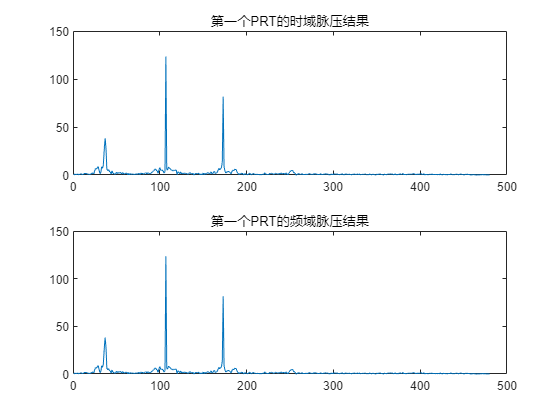


figure();
subplot(2,1,1);plot(abs(pc_time1(1:480)));title('第一个PRT的时域脉压结果');
subplot(2,1,2);plot(abs(pc_freq1(1:480)));title('第一个PRT的频域脉压结果');

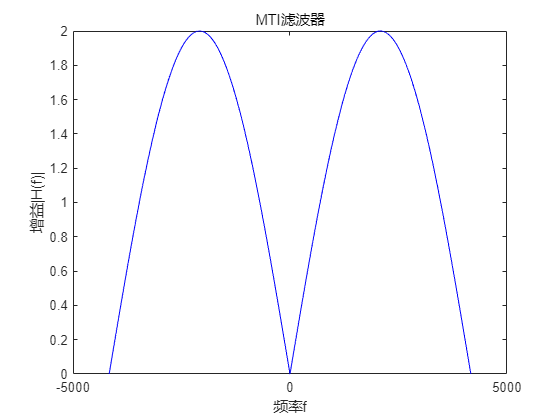

%% ================按照脉冲号、距离门号重排数据=================================%%
for i=1:PulseNumber
    pc(i,1:SampleNumber)=pc_freq1((i-1)*SampleNumber+1:i*SampleNumber);
end

%% ================MTI（动目标显示）,一次对消静止Z目标和低速目标---可抑制杂波=================================%

%% MTI 动目标显示
f=-PRF:PRF;
H=4*(sin(pi*f/PRF)).^2;
figure();
plot(f,(sqrt(H)), 'b');
% hold on;
% plot(f, (H), 'r');
title('MTI滤波器');
xlabel('频率f');
ylabel('增益|H(f)|');

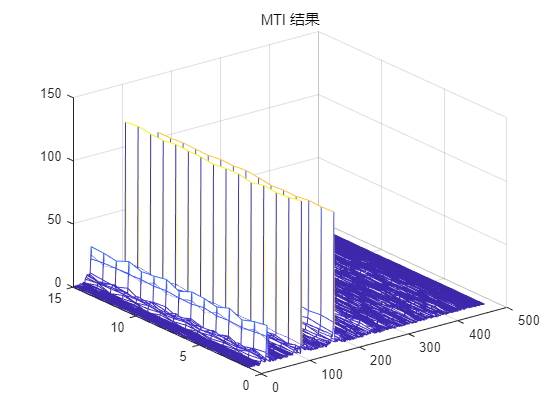


for i=1:PulseNumber-1               %滑动对消，少了一个脉冲
    mti(i,:)=pc(i+1,:)-pc(i,:);
end

figure();
mesh(abs(mti));title('MTI 结果');

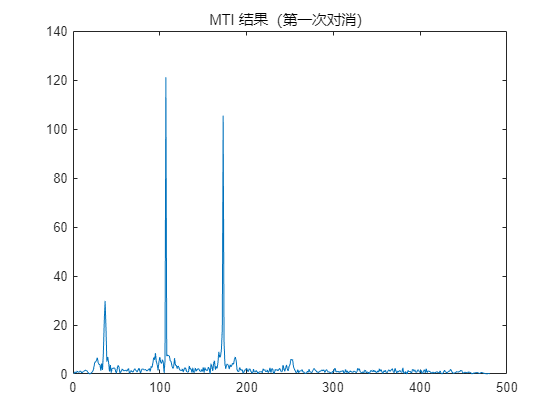

figure();
plot(abs(mti(1,:)));title('MTI 结果（第一次对消）');

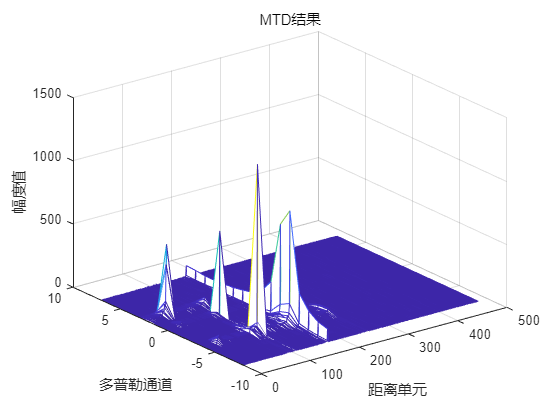

%% ================MTD（动目标检测）,区分不同速度的目标，有测速作用=================================%
mtd=zeros(PulseNumber,SampleNumber);
for i=1:SampleNumber
    buff(1:PulseNumber)=pc(1:PulseNumber,i);
    buff_fft=fftshift(fft(buff)); %用fftshift将零频搬移到中间 这样可以方便观察速度正负
    mtd(1:PulseNumber,i)=buff_fft(1:PulseNumber)';
end
x=1:1:SampleNumber;
y=-8:1:7;%通道这样设后读出的通道数乘单位值则是速度值。
figure();mesh(x,y,abs(mtd));title('MTD结果');xlabel('距离单元');ylabel('多普勒通道');zlabel('幅度值');

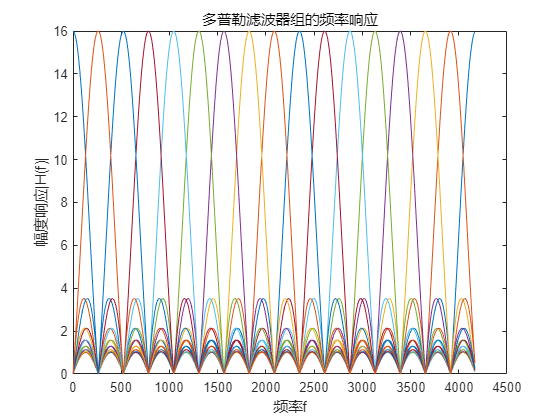

%% MTD 动目标检测
N=16;
for m=1:N
     ww(m,:)=exp(-1j*2*pi*m*(0:N-1)/N);
end
Hd=fftshift(fft(ww,480)); %% FFT窄带滤波器组
y=1:0.1:16;
figure;
plot(linspace(0, PRF,480),abs(Hd));title('多普勒滤波器组的频率响应');xlabel('频率f');ylabel('幅度响应|H(f)|');

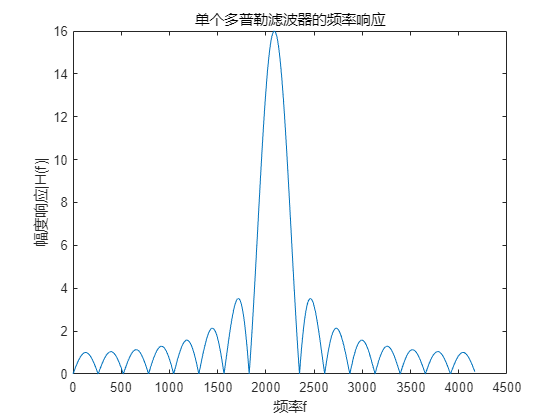

figure;
plot(linspace(0,PRF,480),abs(Hd(:,9)));title('单个多普勒滤波器的频率响应');xlabel('频率f');ylabel('幅度响应|H(f)|');

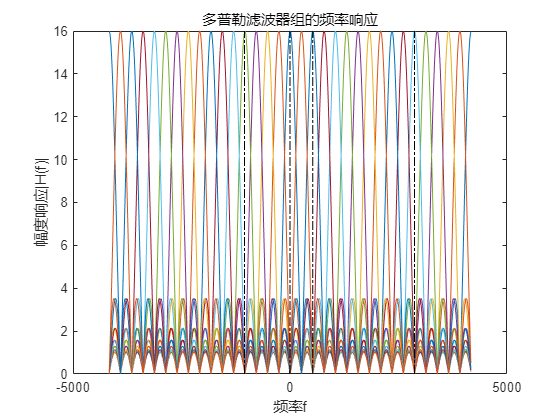

Hd_re = [Hd' Hd']';
figure;
plot(linspace(-PRF,PRF,960),abs(Hd_re));title('多普勒滤波器组的频率响应');xlabel('频率f');ylabel('幅度响应|H(f)|');
hold on;
plot([523,523], [0,16], '-.k');
hold on;
plot([0,0], [0,16], '-.k');
hold on;
plot([-1047,-1047], [0,16], '-.k');
hold on;
plot([2868,2868], [0,16], '-.k');
hold off;

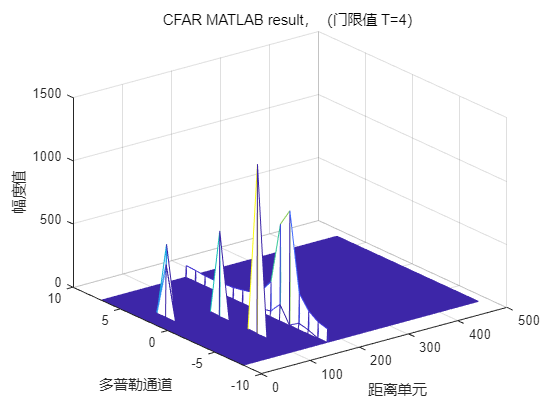

%% CFAR检测部分（GO-CFAR） =================================% 
cfar=zeros(PulseNumber,SampleNumber);
T=4;
for i=1:PulseNumber
    for k=1:2
        left=0;
        mtd_abs = abs(mtd);
        right=mean(mtd_abs(i,k+2:k+17));    %%%%加2是加了一个保护单元，选取16个参考单元做平均
        maxV=max(left,right);
        if(mtd_abs(i,k)>=T*maxV)
            cfar(i,k)=mtd_abs(i,k);
        else
            cfar(i,k)=0;
        end
    end
    for k=3:17
        left=mean(mtd_abs(i,1:k-2));
        right=mean(mtd_abs(i,k+2:k+17));
        maxV=max(left,right);
        if(mtd_abs(i,k)>=T*maxV)
            cfar(i,k)=mtd_abs(i,k);
        else
            cfar(i,k)=0;
        end
    end
    for k=18:SampleNumber-18
        left=mean(mtd_abs(i,k-17:k-2));
        right=mean(mtd_abs(i,k+2:k+17));
        maxV=max(left,right);
        if(mtd_abs(i,k)>=T*maxV)
            cfar(i,k)=mtd_abs(i,k);
        else
            cfar(i,k)=0;
        end
    end
    for k=SampleNumber-17:SampleNumber-2
        left=mean(mtd_abs(i,k-17:k-2));
        right=mean(mtd_abs(i,k+2:SampleNumber));
        maxV=max(left,right);
        if(mtd_abs(i,k)>=T*maxV)
            cfar(i,k)=mtd_abs(i,k);
        else
            cfar(i,k)=0;
        end
    end
    for k=SampleNumber-1:SampleNumber
        left=mean(mtd_abs(i,k-17:k-2));
        right=0;
        maxV=max(left,right);
        if(mtd_abs(i,k)>=T*maxV)
            cfar(i,k)=mtd_abs(i,k);
        else
            cfar(i,k)=0;
        end
    end
end
x=1:1:480;
y=-8:1:7;
figure;mesh(x,y,cfar);title(' CFAR MATLAB result，（门限值 T=4）');
xlabel('距离单元');
ylabel('多普勒通道');
zlabel('幅度值');